# SysMIC M1: Assignment 1

If you need help for this assignment please make use of the [session 1 forum](http://sysmic.ac.uk/moodle/mod/forum/view.php?id=2520) .

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2330](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2330).

After submission you can access model answers via the [session 1 review](http://sysmic.ac.uk/moodle/mod/quiz/view.php?id=3194) activity.

`Name: [ Jade Lau ]`

## Exercise 1.5.2

1. Make a plot of the Fibonacci numbers up to 25. On the x-axis should be the number of the sequence and on the y-axis should be the Fibonacci number. 

What happens to the values as the sequence increases?

**Hint:** For this part you will need to define and fill two arrays, for example:

where `x` array will be set to contain the $i$ values (1 to 25) that will form the x-axis co-ordinates.

and the `y` array will be filled with the corresponding Fibonacci numbers up to 25. 

Once these arrays have been defined, call the `plot` function with your two arrays as the arguments (e.g. `plot(x,y)`).

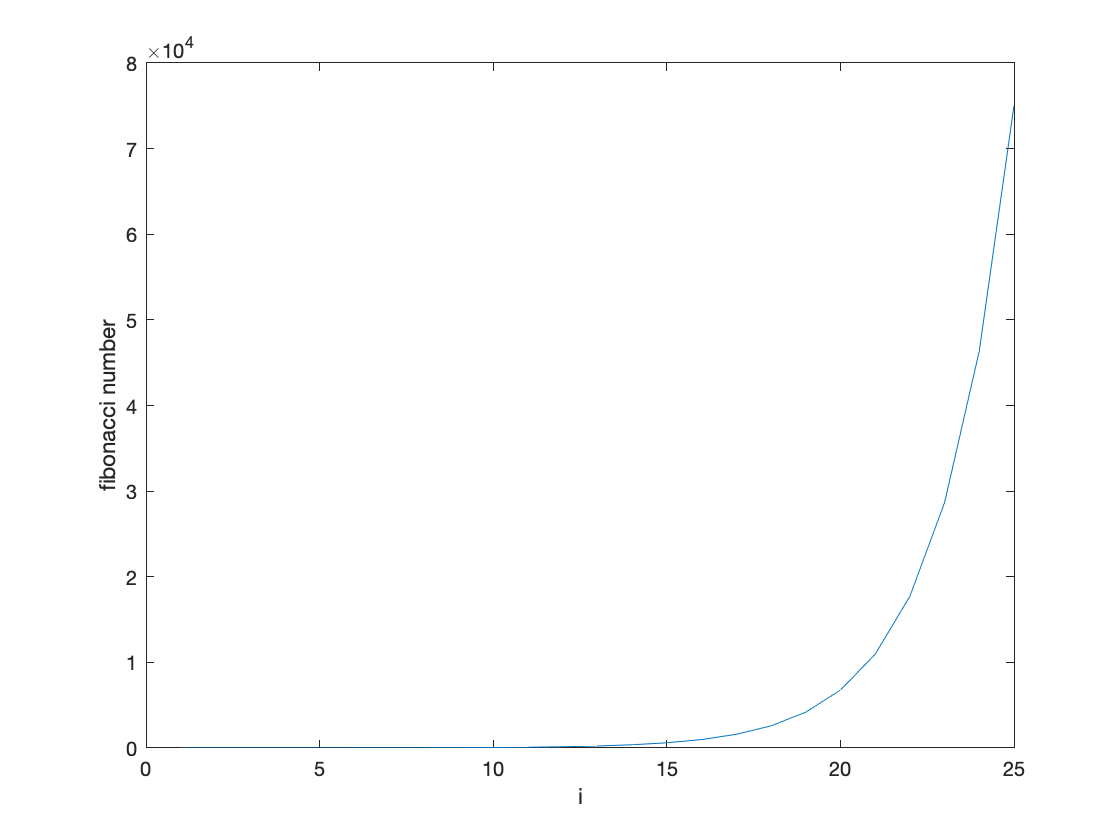

figure();
x = 1:25;
y = fibonacci(25);
plot(x,y);
ylabel('fibonacci number');
xlabel('i');

2. Now make the same plot but instead of plotting the Fibonacci number, plot the logarithm of the Fibonacci number (use the `log` function). What does the plot look like now?

**Hint:** For this part you only need to replace `plot(x,y)` by `plot(x,log(y))` since applying a function to an array applies it to all the elements in the array.

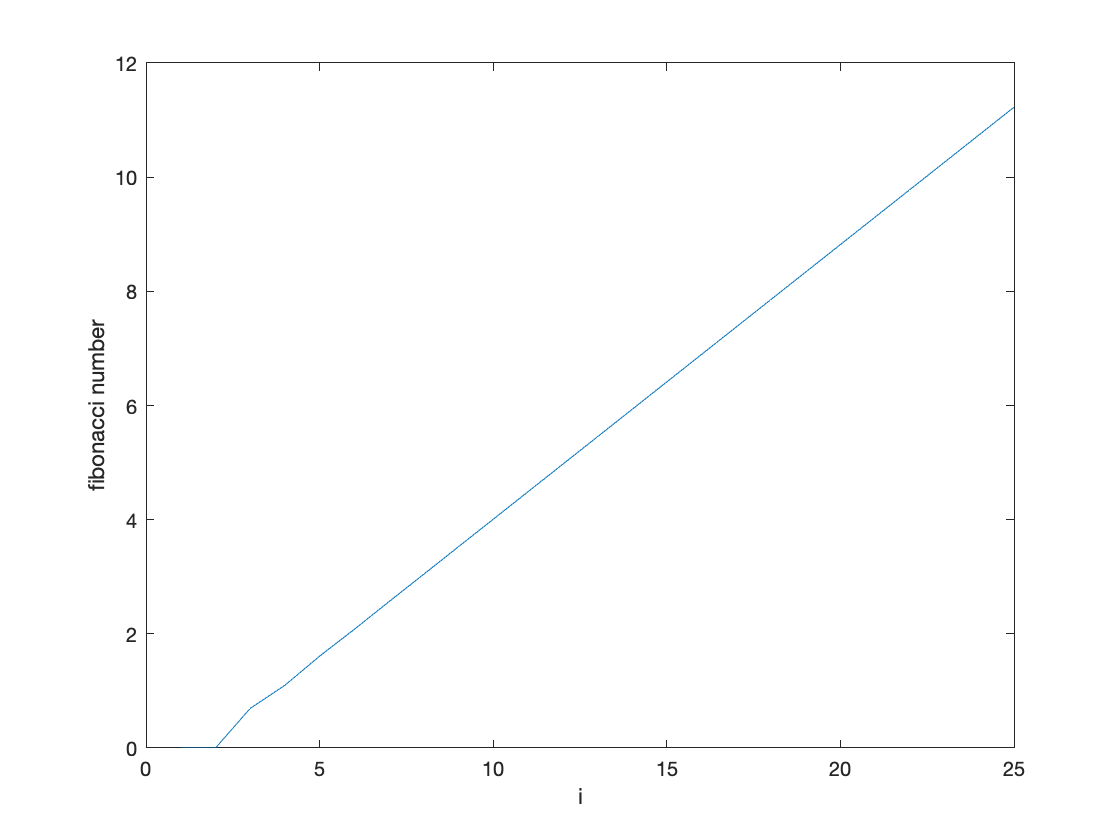

figure();
x = 1:25;
y = fibonacci(25);
plot(x,log(y));
ylabel('fibonacci number');
xlabel('i');

## **Exercise** 1.5.3

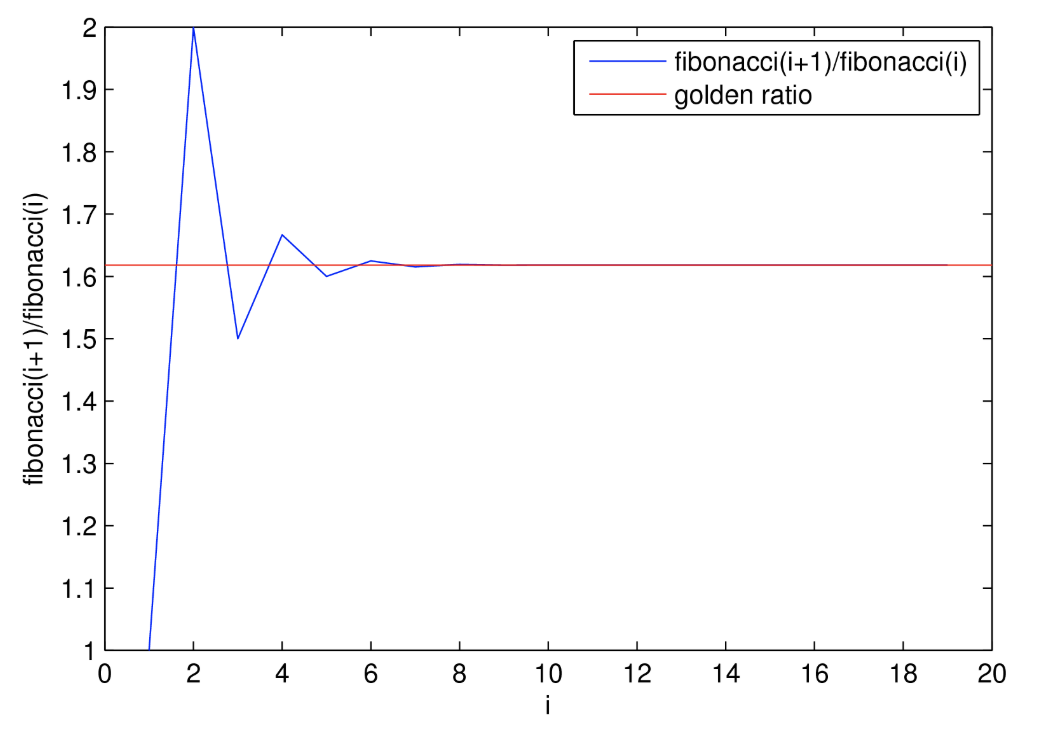

Try to reproduce the plot above showing, for $i=1,\ldotp \ldotp \ldotp 19$ how the ratio of subsequent Fibonacci numbers tends to the Golden ratio $\frac{\left(1+\sqrt{5}\right)}{2}$.

**Hint:** You will need to first calculate the Fibonacci numbers up to 20 and store them in an array (you should have already done this). 

You will then need to create another array to hold the ratios and write a for-loop to fill it, calculating the ratios as in Table [1.5.1](https://sysmic.ac.uk/textbook/1.5-basic-plotting.html#tab:fib2) up to $i=19$. 

To draw the horizontal line at the Golden ratio one way is to store the value in variable `gr`, then add the line using: `plot([0,20],[gr,gr],'r')`.

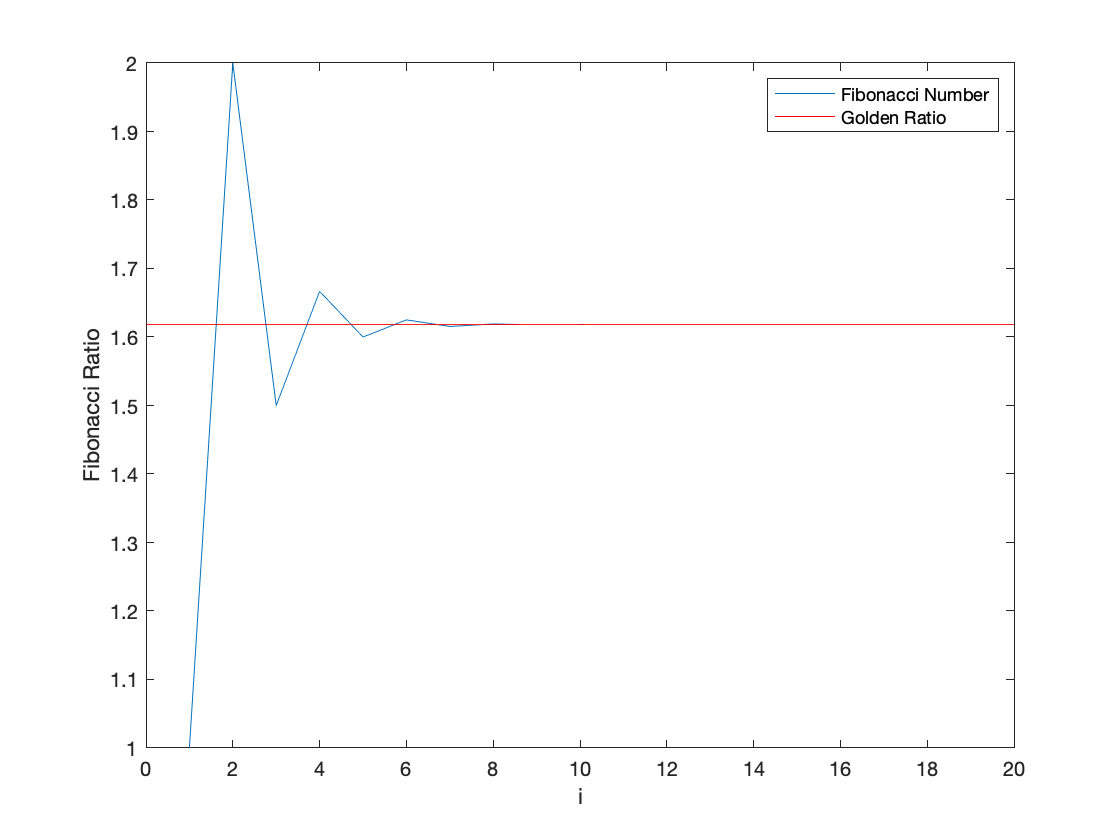

x = 1:20;
fib = fibonacci(21);
ratios = zeros(1,20);
gr = 1.61803398875;
for i=1:20
    ratios(i) = fib(i+1)/fib(i);
end
 
figure();
plot(x, ratios);
hold on;
plot( [0,20],[ gr,gr],'r')
ylabel('Fibonacci Ratio');
xlabel('i');
legend('Fibonacci Number', 'Golden Ratio')

function result = fibonacci(n)
    result = zeros(1,n);
    result(1) = 1;
    result(2) = 1;
    for i=3:n
       result(i)=result(i-1)+result(i-2);
    end
end
